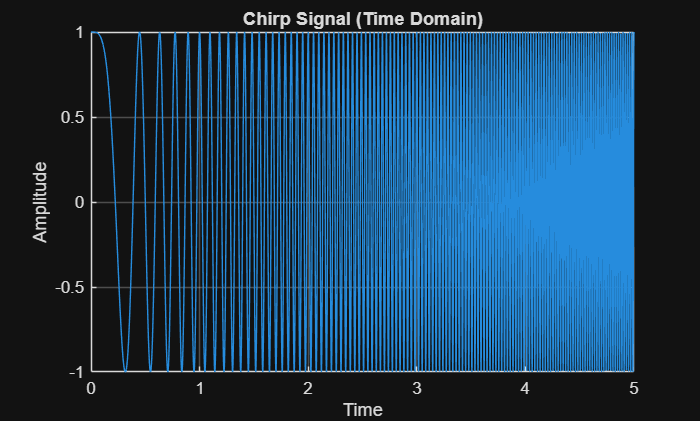

clc;
close all;
clear all;

% Signal whose frequency increases linearly with time
t = 0:0.001:5;

f0 = 0;      % Initial frequency
f1 = 50;     % Final frequency
T = 5;       % Sweep time

S = (f1 - f0) / T;   % Chirp rate

% Chirp Signal Equation
signal = cos(2*pi*(f0*t + (S*t.^2)/2));

% Plot
figure;
plot(t, signal);
xlabel('Time');
ylabel('Amplitude');
title('Chirp Signal (Time Domain)');
grid on;